# Find Spots for every Channel

This script is used for detecting the signals in each channel for direct RNA ISS. 

The fist step is to specify the path of the file analysed. We have 5 files including a single channel on the same image each (4 Detection channels+DAPI). The files are name equally (have the same prefix) but have a different number each after the prefix, specifying the channel.

folder='L:\4plex_assay\200313_r1c1\dRNA_02_tr4_r1c1_ROI2_001\Preprocess\Stitched2DTiles_MIST_Ref1\'

folder = 'L:\4plex_assay\200313_r1c1\dRNA_02_tr4_r1c1_ROI2_001\Preprocess\Stitched2DTiles_MIST_Ref1\'

PREFIX='dRNA_02_tr4_r1c1_ROI2_001_stitched-'

PREFIX = 'dRNA_02_tr4_r1c1_ROI2_001_stitched-'

## Finding spots channel 1

We load the image containnig channel 1 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(1),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, 0.001); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 1 it will be SIG1

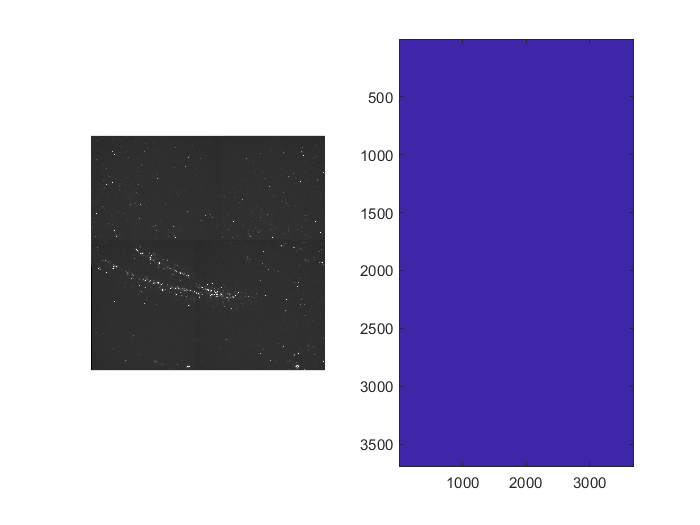

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =         2452           1



 SIG1=[blobs,XY];
 GROUP=1*ones(size(SIG1,1),1);
 SIG1=[SIG1,GROUP];

## Finding spots channel 2

We load the image containnig channel 2 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(2),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, 0.0025); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 2 it will be SIG2

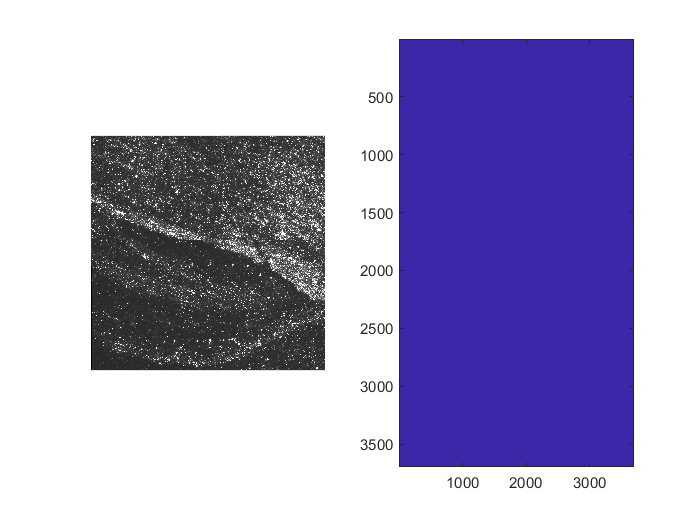

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =        65969           1



 SIG2=[blobs,XY];
 GROUP=2*ones(size(SIG2,1),1);
 SIG2=[SIG2,GROUP];

## Finding spots channel 3

We load the image containnig channel 3 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(3),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, .002); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 3 it will be SIG3

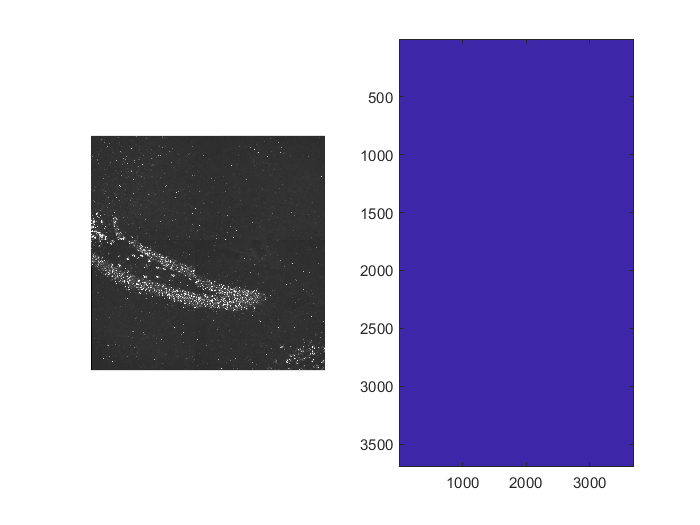

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =        18973           1



 SIG3=[blobs,XY];
 GROUP=3*ones(size(SIG3,1),1);
 SIG3=[SIG3,GROUP];

## Finding spots channel 4

We load the image containnig channel 4 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(4),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, .002); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 4 it will be SIG4

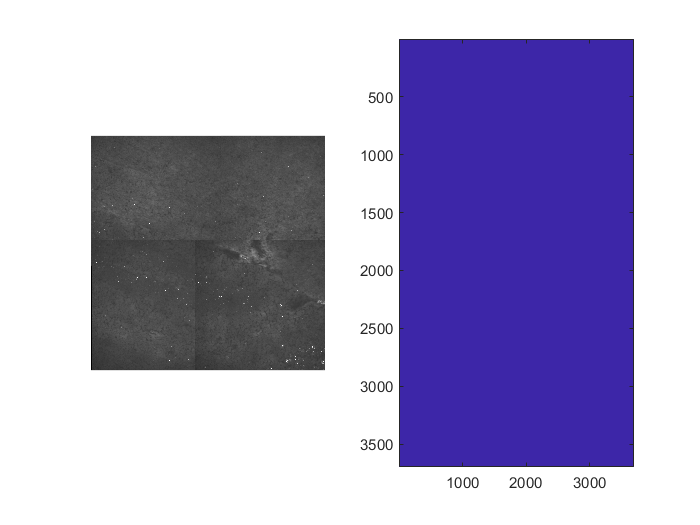

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =         1878           1



 SIG4=[blobs,XY];
 GROUP=4*ones(size(SIG4,1),1);
 SIG4=[SIG4,GROUP];

### Save detected spots

The spots detected in all channels are combined in a matrix and saved in a file

ALL=[SIG1(:,1:4);SIG2(:,1:4);SIG3(:,1:4);SIG4(:,1:4)];
writematrix(ALL,[folder,PREFIX,'_SPOTS_found','.csv']);

### Plot spots found

We first load the DAPI,which in our case is in channel 5. Then, we plot all together

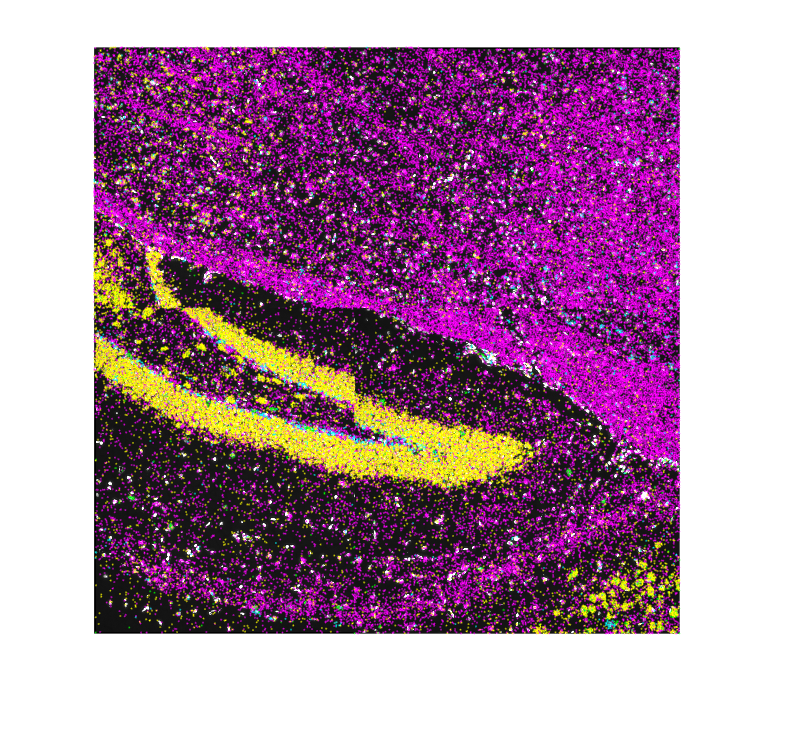

IDAPI=imread([folder,PREFIX,num2str(5),'.tif']);
figure
imshow(IDAPI*40);
hold on 
gscatter(SIG2(:,3),SIG2(:,2),[],'m','.',0.01,'filled')
hold on
gscatter(SIG1(:,3),SIG1(:,2),[],'c','.',0.01,'filled')
hold on
gscatter(SIG4(:,3),SIG4(:,2),[],'g','.',0.01,'filled')
hold on
gscatter(SIG3(:,3),SIG3(:,2),[],'y','.',0.01,'filled')